dt=1/1000;
t = 0:dt:0.5;
u1 = sin(2*pi*50*t);
u2 = sin(2*pi*100*t);
u3 = 0*sin(2*pi*75*t);

u = u1+u2+u3;
M=300;
H = hankel(u(1:M),u(M:end));

[U,S,V]=svd(H);

rr=rank(H)

rr = 4

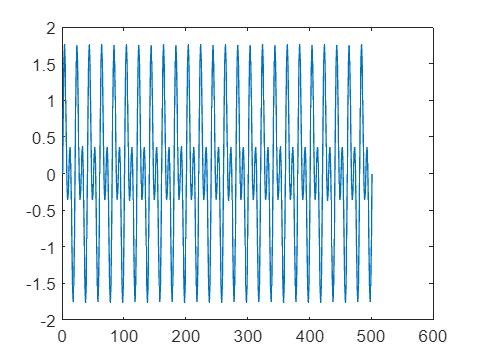

figure; plot(u)

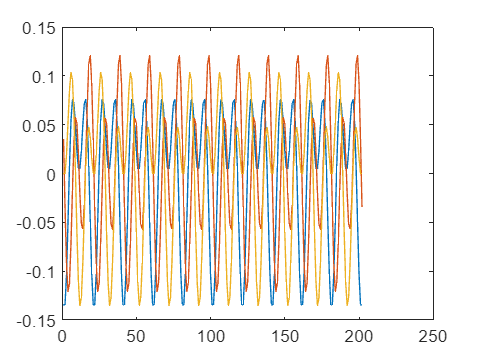

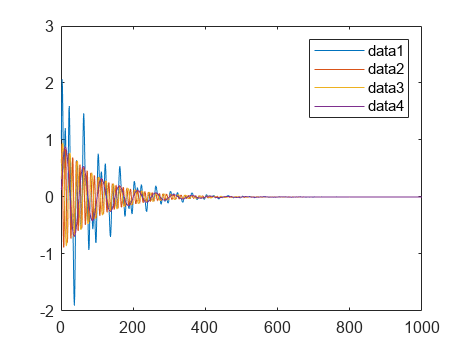

hankelSeries =     1.0120    1.7521    2.0653    1.9414    1.5103    0.9868    0.5860    0.4441    0.5722    0.8606    1.1297    1.2074    1.0011    0.5381   -0.0421   -0.5403   -0.7726   -0.6418   -0.1755    0.4812    1.1174    1.5304    1.5960    1.3091    0.7788    0.1835   -0.2983   -0.5528   -0.5691   -0.4354   -0.2976   -0.2957   -0.5049   -0.9026   -1.3749   -1.7589   -1.9051   -1.7349   -1.2723   -0.6375   -0.0053    0.4563    0.6437    0.5502    0.2628   -0.0748   -0.3189   -0.3787   -0.2476    0.0000
    1.7521    2.0653    1.9414    1.5103    0.9868    0.5860    0.4441    0.5722    0.8606    1.1297    1.2074    1.0011    0.5381   -0.0421   -0.5403   -0.7726   -0.6418   -0.1755    0.4812    1.1174    1.5304    1.5960    1.3091    0.7788    0.1835   -0.2983   -0.5528   -0.5691   -0.4354   -0.2976   -0.2957   -0.5049   -0.9026   -1.3749   -1.7589   -1.9051   -1.7349   -1.2723   -0.6375   -0.0053    0.4563    0.6437    0.5502    0.2628   -0.0748   -0.3189   -0.3787   -0.2476    

ar_model =
Discrete-time AR model: A(z)y(t) = e(t)                                                                            
  A(z) = 1 - 7.126 z^-1 + 22.99 z^-2 - 43.79 z^-3 + 53.84 z^-4 - 43.75 z^-5 + 22.95 z^-6 - 7.107 z^-7 + 0.9965 z^-8
                                                                                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=8
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                          
Estimated using AR ('fb/now') on time domain data "train_series".
Fit to estimation data: 100%                                     
FPE: 5.668e-11, MSE: 5.578e-11                                   
 


    "Prediction using full time series (no noise): -9.5476e-05"
    "Prediction using full time series (no noise): -9.9543e-05"
    "Prediction using full time series (no noise): -8.2706e-05"
    "Prediction using full time series (no noise): -4.6597e-05"
    "Prediction using full time series (no noise): 6.8875e-07"



    "Ground truth: -9.5479e-05"
    "Ground truth: -9.9563e-05"
    "Ground truth: -8.2793e-05"
    "Ground truth: -4.6871e-05"
    "Ground truth: 6.9033e-19"




%kunnen we dmv de values van V en die individueel gebruiken om het volgende
%punt te voorspelen mogelijk een betere voorspelling doen dan als we het
%gecombineerde gebruiken om het volgende punt te voorspellen?
figure; plot(V(:,1));
hold all; plot(V(:,2));
plot(V(:,3))

clear all;
format long;

% Parameters
N = 500;  % Number of points in the time series
num_predict = 1;
L = floor((N-1) / 2);
num_experiments = 100;  % Number of experiments to perform
optimal_order = 1;  % Set a fixed optimal order for simplicity

% Generate sinusoidal signals
t = (1:N)';
signal1 = sin(2 * pi * 0.1 * t) .* exp(-0.01 * t) +rand*10 ;
signal2 = sin(2 * pi * 0.05 * t) .* exp(-0.01 * t) -rand()*10 %;

signal2 =   -9.090890551600973
  -8.820686451021198
  -8.611725846751551
  -8.483067718614175
  -8.445603351006843
  -8.501161479026591
  -8.642510329753470
  -8.854238600951382
  -9.114412507569508
  -9.396832775507557


signal3 = sin(2 * pi * 0.02 * t) .* exp(-0.01 * t) +rand()*10 %;

signal3 =    1.185344616741192
   1.305023967151404
   1.418503297629995
   1.524122312037365
   1.620377096955783
   1.705940655618986
   1.779680255407444
   1.840671379429235
   1.888208130213348
   1.921809992298388


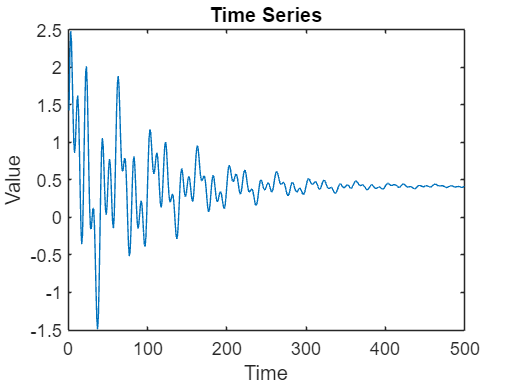


% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Plot the time series
figure;
plot(time_series);
title('Time Series');
xlabel('Time');
ylabel('Value');


% Ground truth for point 100
ground_truths = zeros(num_experiments,1);

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_components = zeros(num_experiments, 1);

% Visualize the singular values of the Hankel matrix
H2D = hankel(time_series(1:L), time_series(L:end-1));
[U, S, V] = svd(H2D, 'econ');
singular_values = diag(S);

rank(H2D)

ans =      7


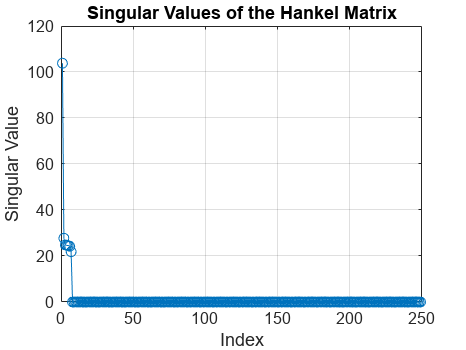

figure;
plot(singular_values, 'o-');
title('Singular Values of the Hankel Matrix');
xlabel('Index');
ylabel('Singular Value');
grid on;

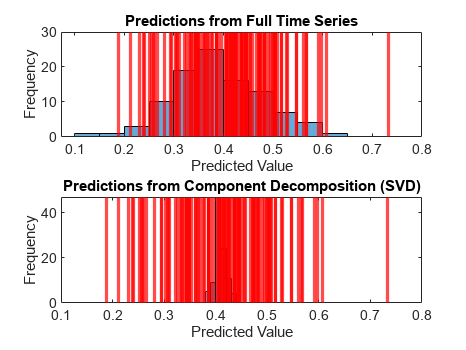


rel_error_full = zeros(num_experiments,1);
rel_error_SVD = zeros(num_experiments,1);


% Perform the experiment
for exp = 1:num_experiments 
    % Add noise (for testing with noise, if needed)
    noisy_series = time_series;  % No noise added in this case
    noisy_series = time_series+ randn(N, 1) * 0.1;  % No noise added in this case

    ground_truths(exp) = noisy_series(end);


    training_range = noisy_series(1:N-num_predict);
    
    % 1. Full time series prediction using AR model
    model_full = ar(noisy_series(1:N-1), optimal_order);  % AR(optimal_order) model
    pred_full = forecast(model_full, training_range, num_predict);
    predictions_full(exp) = pred_full(end);

    % 2. Decomposition using Hankel matrix (SVD)
    %H2Dzeros = hankel(noisy_series(1:N-1));
    H2Dzeros = hankel(noisy_series(1:L),noisy_series(L:end-1));
    [U, S, V] = svd(H2Dzeros, 'econ');    

    num_components = 7;
    c = zeros(L, N-L, num_components);
    pred_components = zeros(num_components, 1);

    
    figure;
    
    %plot(time_series)
    for comp = 1:num_components
        %tensor for holding all components (which are matrices)
        c(:,:,comp) = U(:,comp)*S(comp,comp)*V(:,comp)';

        %component_series = [c(:,1,comp);c(end,2:end,comp)'];
        % Convert component matrix back to time series by averaging along anti-diagonals
        component_series = zeros(N-1, 1);
        counts = zeros(N-1, 1);
        for i = 1:L
            for j = 1:(N-L)
                component_series(i+j-1) = component_series(i+j-1) + c(i,j,comp);
                counts(i+j-1) = counts(i+j-1) + 1;
            end
        end
        component_series = component_series ./ counts;



        %hold on;
        %plot(component_series);
        model_comp = ar(component_series, optimal_order);
        pred_comp = forecast(model_comp, component_series, num_predict);
        pred_components(comp) = pred_comp(end);
    end
    %legend({'Original', 'c1', 'c2', 'c3', 'c4', 'c5', 'c6', 'c7'});
    %hold off;

    %{
    c1 = S(1,1)*U(:,1)*V(:,1)';
    c2 = S(2,2)*U(:,2)*V(:,2)';
    c3 = S(3,3)*U(:,3)*V(:,3)';
    

    component_series1 = [c1(:,1);c1(end,2:end)'];
    model_comp = ar(component_series1, optimal_order);
    pred_comp = forecast(model_comp, component_series1, num_predict);
    pred_components(1) = pred_comp(end);
    
    component_series2 = [c2(:,1);c2(end,2:end)'];
     model_comp = ar(component_series2, optimal_order);
    pred_comp = forecast(model_comp, component_series2, num_predict);
    pred_components(2) = pred_comp(end);

    component_series3 = [c3(:,1);c3(end,2:end)'];
    model_comp = ar(component_series3, optimal_order);
    pred_comp = forecast(model_comp, component_series3, num_predict);
    pred_components(3) = pred_comp(end);


    %}
    predictions_components(exp) = sum(pred_components);


    
    %{
    components1 = U1(:, 1:num_components) * S1(1:num_components, 1:num_components) * V1(:, 1:num_components)';

    %{
    % Visualize components
    figure;
    for comp = 1:num_components
        subplot(num_components, 1, comp);
        plot(components1(:, comp));
        title(['Component ', num2str(comp)]);
    end
    %}

    % 3. Predict each component separately with zero initial conditions
    pred_components1 = zeros(num_components, 1);
    for comp = 1:num_components
        model_comp1 = ar(components1(:, comp), optimal_order);  %CHECK THIS OUT!!!! SHOULD TRAIN ar on entire matrix 
        pred_comp1 = forecast(model_comp1, components1(:, comp), num_predict);
        pred_components1(comp) = pred_comp1(end);
    end
    %}

    %predictions_components(exp) = sum(pred_components1);
    rel_error_full(exp) = abs(predictions_full(exp)-ground_truths(exp))/abs(ground_truths(exp));
    rel_error_SVD(exp) = abs(predictions_components(exp)-ground_truths(exp))/abs(ground_truths(exp));
end

% Compare predictions
figure;
subplot(2, 1, 1);
histogram(predictions_full);
title('Predictions from Full Time Series');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truths, 'r', 'LineWidth', 2);  % Ground truth line

subplot(2, 1, 2);
histogram(predictions_components);
title('Predictions from Component Decomposition (SVD)');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truths, 'r', 'LineWidth', 2);  % Ground truth line

standard

% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp("Mean: ");

Mean: 


disp(mean(predictions_full));

  -4.7462e-15



disp("SD: ")

SD: 


disp(std(predictions_full));

     0



disp("RMSE: ");

RMSE: 


disp(rmse(predictions_full,ground_truths));

   1.2349e-14



disp('Mean Relative error of Full Time Series Predictions');

Mean Relative error of Full Time Series Predictions


disp(mean(rel_error_full));

     0




errors_full = [mean(predictions_full);std(predictions_full);rmse(predictions_full,ground_truths);mean(rel_error_full)]

errors_full = 1.0e-13 *

   -0.0475
         0
    0.1235
         0



disp('Component Decomposition Predictions (SVD):');

Component Decomposition Predictions (SVD):


disp("Mean: ");

Mean: 


disp(mean(predictions_components));

     0



disp("SD: ")

SD: 


disp(std(predictions_components));

     0



disp("RMSE: ");

RMSE: 


disp(rmse(predictions_components,ground_truths));

   7.6027e-15



disp('Mean Relative error of Component Decomposition Predictions');

Mean Relative error of Component Decomposition Predictions


disp(mean(rel_error_SVD));

     0




errors_SVD = [mean(predictions_components);std(predictions_components);rmse(predictions_components,ground_truths);mean(rel_error_SVD)]

errors_SVD = 1.0e-14 *

         0
         0
    0.7603
         0


with noise

% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp("Mean: ");

Mean: 


disp(mean(predictions_full));

  -0.224913859282752



disp("SD: ")

SD: 


disp(std(predictions_full));

   0.209499186325090



disp("RMSE: ");

RMSE: 


disp(rmse(predictions_full,ground_truths));

   0.310754893032458



disp('Mean Relative error of Full Time Series Predictions');

Mean Relative error of Full Time Series Predictions


disp(mean(rel_error_full));

  11.149053163262094




errors_full = [mean(predictions_full);std(predictions_full);rmse(predictions_full,ground_truths);mean(rel_error_full)]

errors_full =   -0.224913859282752
   0.209499186325090
   0.310754893032458
  11.149053163262094



disp('Component Decomposition Predictions (SVD):');

Component Decomposition Predictions (SVD):


disp("Mean: ");

Mean: 


disp(mean(predictions_components));

   0.009110761899397



disp("SD: ")

SD: 


disp(std(predictions_components));

   0.035219603389052



disp("RMSE: ");

RMSE: 


disp(rmse(predictions_components,ground_truths));

   0.111588659967641



disp('Mean Relative error of Component Decomposition Predictions');

Mean Relative error of Component Decomposition Predictions


disp(mean(rel_error_SVD));

   1.641441486691027




errors_SVD = [mean(predictions_components);std(predictions_components);rmse(predictions_components,ground_truths);mean(rel_error_SVD)]

errors_SVD =    0.009110761899397
   0.035219603389052
   0.111588659967641
   1.641441486691027


with noise, decay

% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp("Mean: ");

Mean: 


disp(mean(predictions_full));

   0.029435161028276



disp("SD: ")

SD: 


disp(std(predictions_full));

   0.106413684210555



disp("RMSE: ");

RMSE: 


disp(rmse(predictions_full,ground_truths));

   0.142076498414895



disp('Mean Relative error of Full Time Series Predictions');

Mean Relative error of Full Time Series Predictions


disp(mean(rel_error_full));

   5.647492053572562




errors_full = [mean(predictions_full);std(predictions_full);rmse(predictions_full,ground_truths);mean(rel_error_full)]

errors_full =    0.029435161028276
   0.106413684210555
   0.142076498414895
   5.647492053572562



disp('Component Decomposition Predictions (SVD):');

Component Decomposition Predictions (SVD):


disp("Mean: ");

Mean: 


disp(mean(predictions_components));

     5.694324068940274e-05



disp("SD: ")

SD: 


disp(std(predictions_components));

   0.016141569310046



disp("RMSE: ");

RMSE: 


disp(rmse(predictions_components,ground_truths));

   0.099458116294232



disp('Mean Relative error of Component Decomposition Predictions');

Mean Relative error of Component Decomposition Predictions


disp(mean(rel_error_SVD));

   2.072529709000671




errors_SVD = [mean(predictions_components);std(predictions_components);rmse(predictions_components,ground_truths);mean(rel_error_SVD)]

errors_SVD =    0.000056943240689
   0.016141569310046
   0.099458116294232
   2.072529709000671


with noise, decay, without zero initial conditions

% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp("Mean: ");

Mean: 


disp(mean(predictions_full));

   0.388680232013131



disp("SD: ")

SD: 


disp(std(predictions_full));

   0.092079742722040



disp("RMSE: ");

RMSE: 


disp(rmse(predictions_full,ground_truths));

   0.132893140348779



disp('Mean Relative error of Full Time Series Predictions');

Mean Relative error of Full Time Series Predictions


disp(mean(rel_error_full));

   0.262189163907789




errors_full = [mean(predictions_full);std(predictions_full);rmse(predictions_full,ground_truths);mean(rel_error_full)]

errors_full =    0.388680232013131
   0.092079742722040
   0.132893140348779
   0.262189163907789



disp('Component Decomposition Predictions (SVD):');

Component Decomposition Predictions (SVD):


disp("Mean: ");

Mean: 


disp(mean(predictions_components));

   0.409116305379643



disp("SD: ")

SD: 


disp(std(predictions_components));

   0.010661790307827



disp("RMSE: ");

RMSE: 


disp(rmse(predictions_components,ground_truths));

   0.100558900731797



disp('Mean Relative error of Component Decomposition Predictions');

Mean Relative error of Component Decomposition Predictions


disp(mean(rel_error_SVD));

   0.218019936846519




errors_SVD = [mean(predictions_components);std(predictions_components);rmse(predictions_components,ground_truths);mean(rel_error_SVD)]

errors_SVD =    0.409116305379643
   0.010661790307827
   0.100558900731797
   0.218019936846519
